clear
load vibstand.mat
fs=avtb_2019_Machine_1_02_Motor_bearing_metadata.SamplingRate

fs = 25000

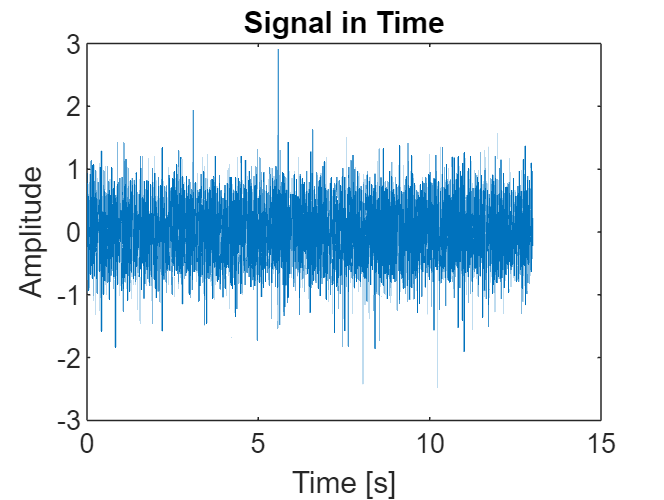


x=avtb_2019_Machine_1_02_Motor_bearing(:,2);
% N=length(x)
% t=(0:N-1)/fs;
% 
% plot(t,x)
% N=N/8
% % downsample
% fs=fs/8
% spectrogram
% x=x(1:8:end);
% length(x)
% 
% t=(0:N-1)/fs;
% length(t)
% plot(t,x)
downsampleRate=8;
[x,t,metadata]=plotSignal(x,fs,downsampleRate);                

Y=fft(x);
mag=abs(Y);
phase=angle(Y);
N=metadata.N

N = 40625

df=fs/N;
f=0:df:fs-df

f = 1.0e+04 *

         0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030


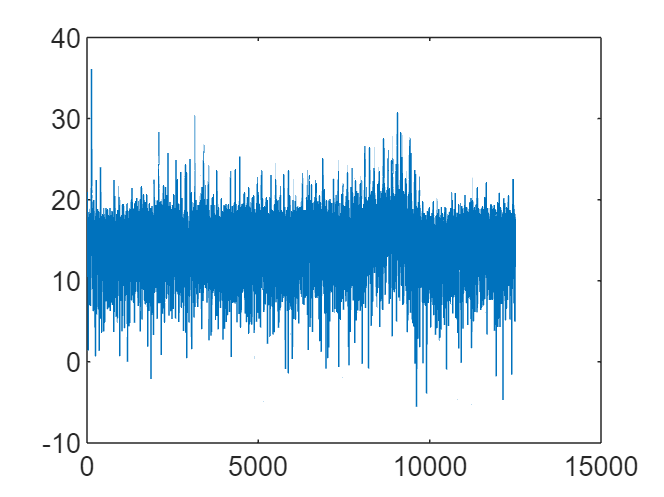


 plot(f(1:end/2),10*log10(mag(1:end/2)))

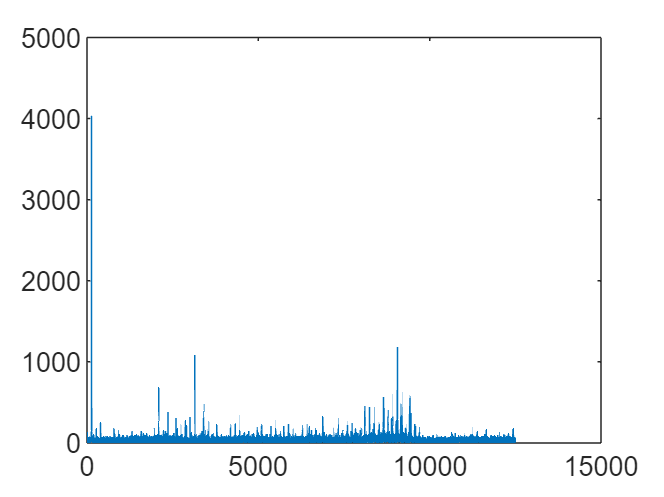

ans = 1.0e+04 *

         0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030



freqPlot(x,fs)